## Importar las señales necesarias

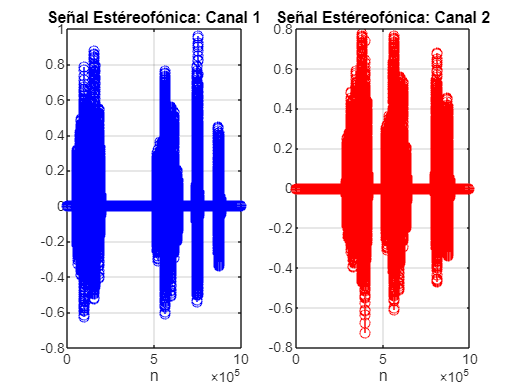

function [signal, sample_rate] = import_signal()
    % Busca el archivo que se quiere importar
    [filename, path] = uigetfile({'*.mp3;*.wav'}); 
    % figure(app.UIFigure);
    fullFileName = fullfile(path, filename);  % Construye la ruta completa del archivo
    
    % Recuperar los datos importados
    [signal, sample_rate] = audioread(fullFileName);
end

function plot_the_signal(stereo_signal)
    figure
    subplot(1,2,1); stem(stereo_signal(:,1),'b');grid on;
    title('Señal Estéreofónica: Canal 1'); xlabel('n');
    subplot(1,2,2); stem(stereo_signal(:,2),'r');grid on;
    title('Señal Estéreofónica: Canal 2'); xlabel('n');
end

[stereo_signal, sample_rate] = import_signal();

plot_the_signal(stereo_signal);


% sound(stereo_signal, sample_rate);

% pause(20);

## Preprocesamiento señal importada

preprocessed_signal = preprocesamiento(stereo_signal, 'Between -1 y 1');

You are using the normalize function -1 to 1


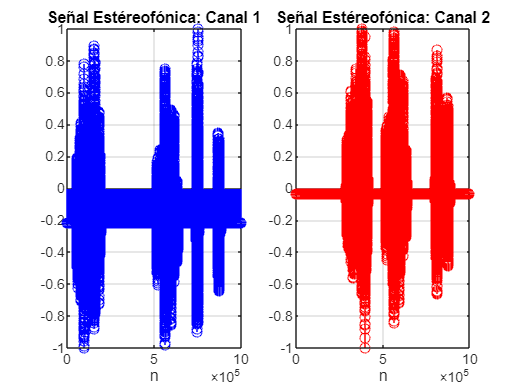


plot_the_signal(preprocessed_signal);


% sound(preprocessed_signal, sample_rate);

## Procesamiento

[signal, sample_rate] = procesamiento_en_el_tiempo('desplazar');

plot_the_signal(signal);

sound(stereo_signal, sample_rate);

## Generar señales

clc; clear vars;

disp('Se seleccionó la Seno');

Se seleccionó la Seno


dlgtitle = 'Sine Signal Parameters';
prompt = {'Ganancia:','Frecuencia Análoga:','Frecuencia Muestreo:', 'Fase (rad)' ,'Desplazamiento:','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','100','44100','0','0', '0', '50000'};
answer = inputdlg(prompt, dlgtitle, dims, defect_input);

A=str2num(answer{1}); % Ganancia de la exponencial

Index exceeds the number of array elements. Index must not exceed 0.

Fa=str2num(answer{2}); % Frecuencia análoga
Fs=str2num(answer{3}); % Frecuencia de muestreo

Fase=str2num(answer{4}); % Fase de la señal análoga (Rad)

n0=str2num(answer{5});
ni=str2num(answer{6});
nf=str2num(answer{7});

% disp(answer{1});
% disp(answer{6});

Ts=1/Fs; %Periodo de muestreo

n6=ni:nf; %Instantes de tiempo

t = n6*Ts; % Time vector en segundos dependiente del tiempo de muestreo

variable = (2*pi*Fa*(n6-n0)/Fs+ Fase);
result = 2*pi*Fa/Fs+ Fase;
x = A*[sin(2*pi*Fa*t + Fase)]; %/(2*pi*Fa*(-55)/Fs+ Fase);

sample_rate = Fs;

figure;
stem(n6,x);
% xlabel('n'); ylabel('x(n)'); title(['Señal Senoidal, Fa=' num2str(Fa) ' Fs= ' num2str(Fs)]);grid on
title('Señal seno');
xlabel('n');
grid('on');

sound(x, sample_rate);

pause(5);

transposed_signal = x.';

preprocessed_signal = preprocesamiento(transposed_signal, 'Between -1 y 1');


figure;
stem(n6, preprocessed_signal);
% xlabel('n'); ylabel('x(n)'); title(['Señal Senoidal, Fa=' num2str(Fa) ' Fs= ' num2str(Fs)]);grid on
title('Señal seno');
xlabel('n');
grid('on');

sound(preprocessed_signal, sample_rate);
